# Milling and Welding Todo

### **Grup 11- Estudiants:**

- **Pol Casacuberta Gil**

- **Marta Granero i Martí**

**Link: **https://drive.matlab.com/sharing/b8a7f88a-dcb6-4c09-a328-ba6c7e737807

See the video: [https://youtu.be/cVZWm9ORY30](https://youtu.be/cVZWm9ORY30)

As you can see in the video a Robot Arm perform three task. Only two tasks are shown: 

- Make a hole in a cylinder by drilling it. Observe that the tool mantain the same orientation during the drilling task.

- Insertion of a smaller cylinder not recorder here. 

- Welding the two cylinder. Observe that the tool always form a 45º with respect to  red cylinder axis

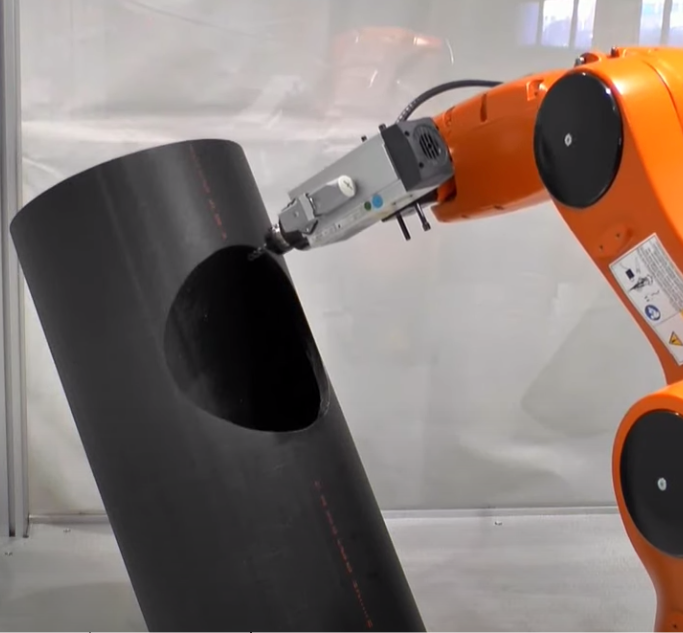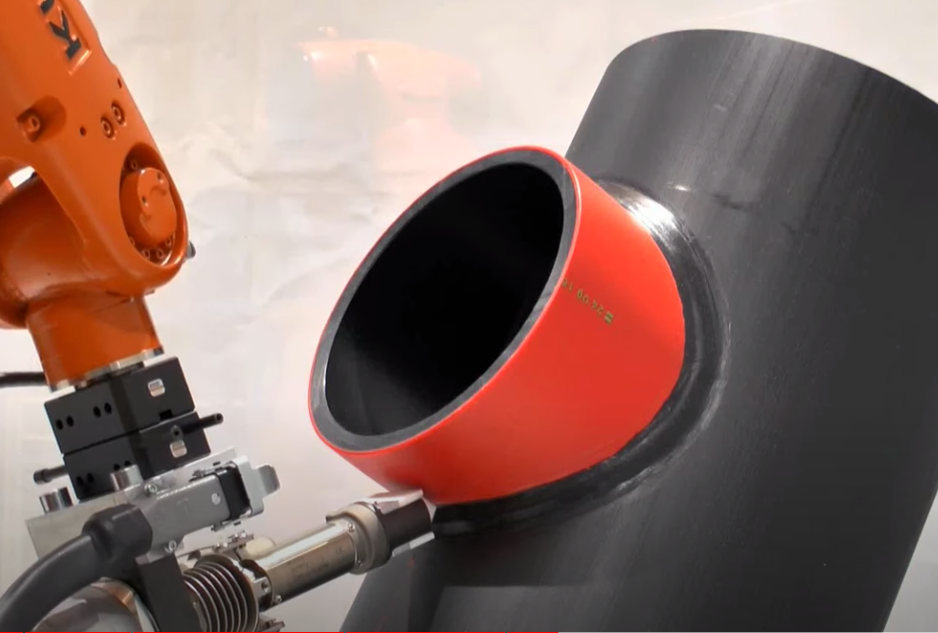

## Sketching your ideas

Conceptualize the problem. Add a sketch and make some small scripts

clear;
close all;
clf
load('F_V_cylinder.mat');

## **Formalize the problem**

Add sections and subsections to make the problem understandable among other engineers colleagues.

### Showing our workspace

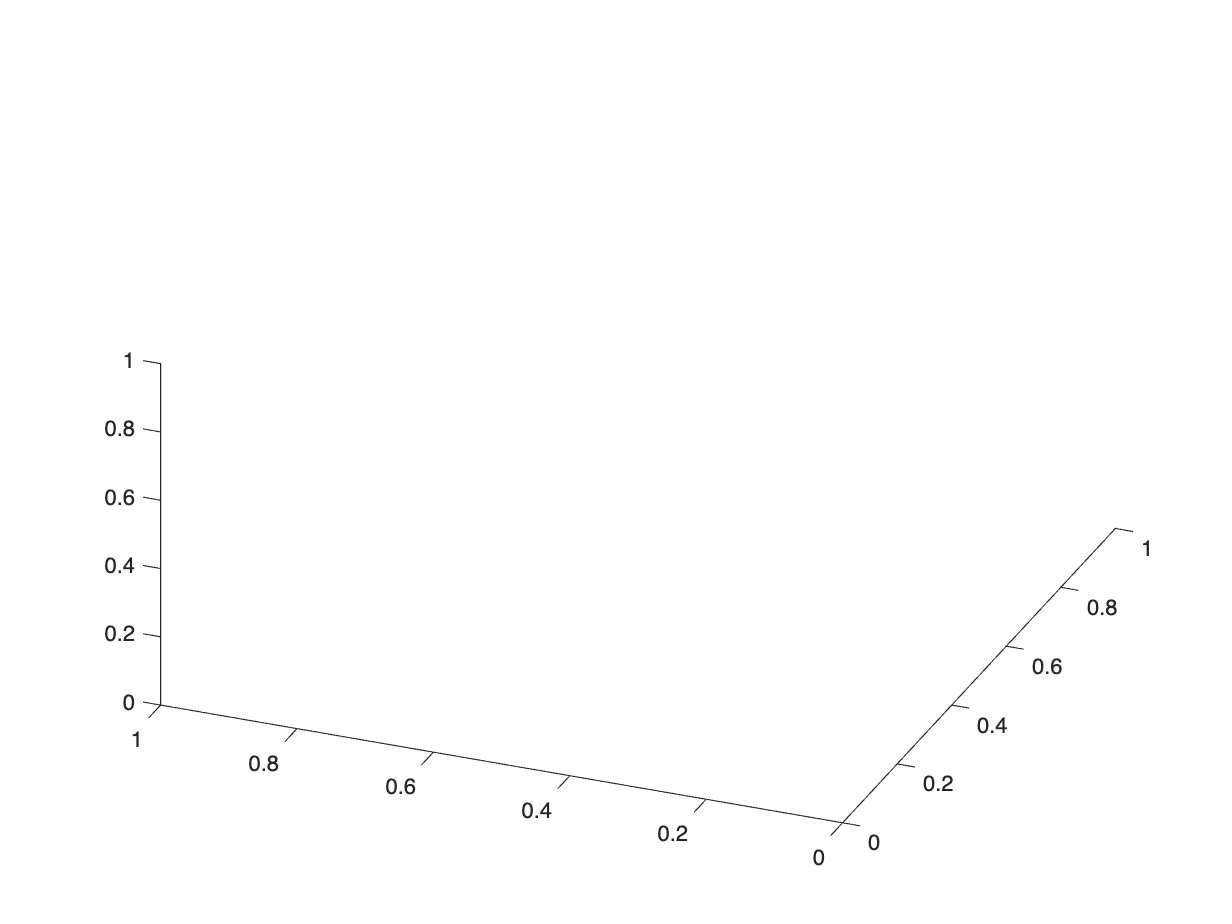

v = [-5 -2 5];
[caz,cel] = view(v);

### **Drawing cylinders**

In this section we calculate the coordinates of the two cylinders and we plot them.

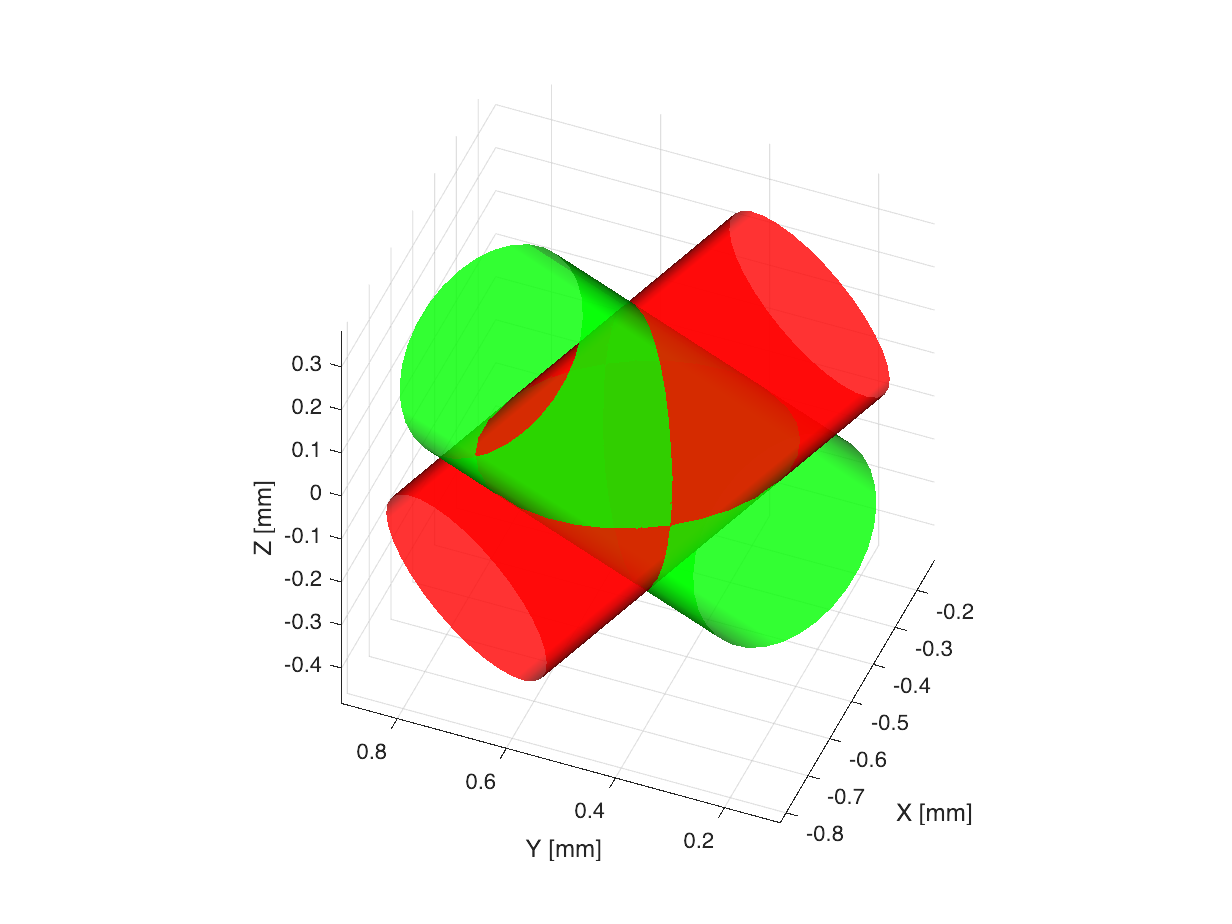

%scale of cylinders
Cy_scale = 0.20;

%position of both cylinders
CY_pose = eye(4)*transl([-0.3 0.3 -0.35])*troty(-pi/6)*trotx(-pi/6);
CY_pose2 = CY_pose * transl(0,0,0.4) * trotx(-pi/2) * troty(-pi/4) * transl(0,0, -0.4);

%scale of both cylinders
V_cy_drill = CY_pose*[Cy_scale.*V_cy'; ones(1,length(V_cy))];
V_cy_drill2 = CY_pose2*[Cy_scale.*V_cy'; ones(1,length(V_cy))]; 

%plotting of both cylinders
FVsPlot(F_cy,V_cy_drill(1:3,:)',[0 1 0])
FVsPlot(F_cy,V_cy_drill2(1:3,:)',[1 0 0])

### **Inicialization**

In this section we initialize some constants and we plot our workspace

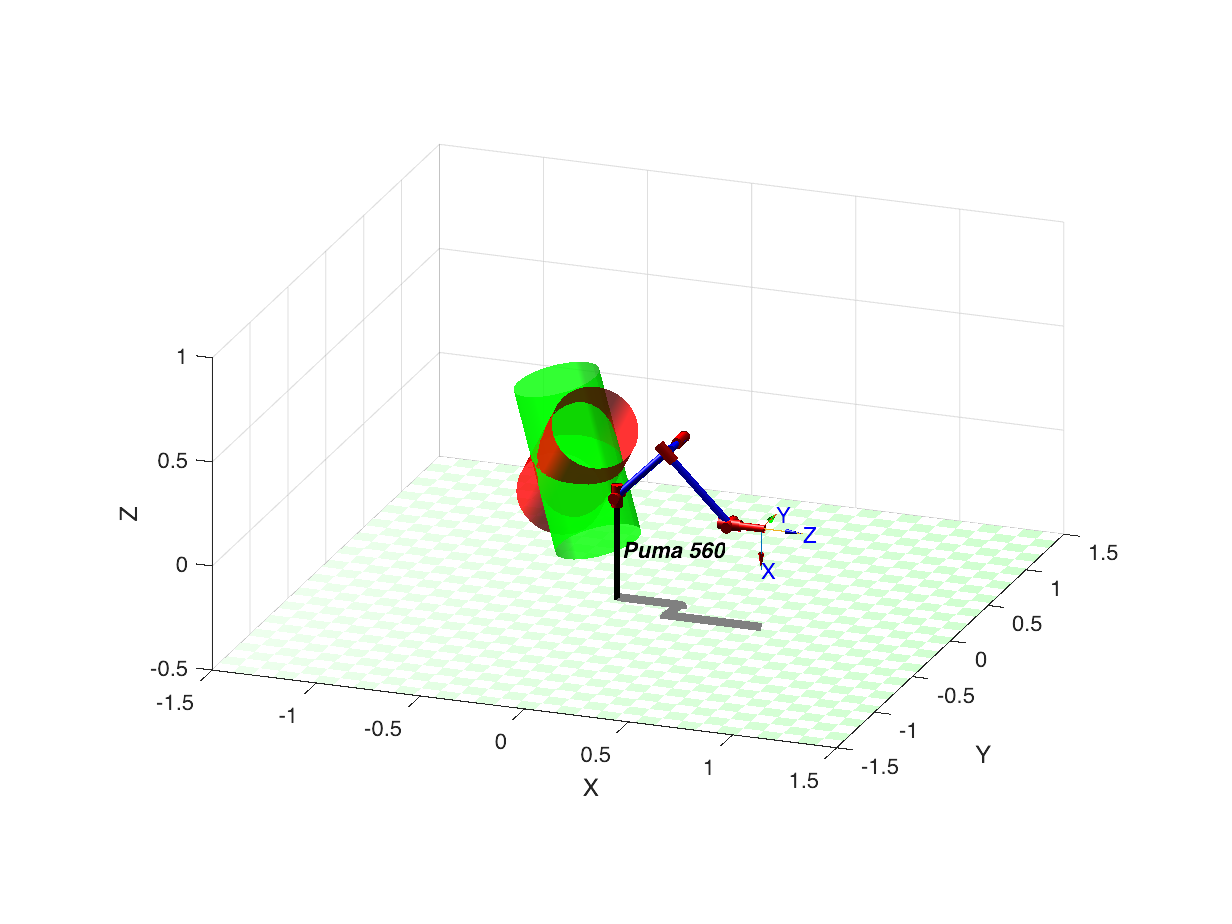

radius = 0.20;
mdl_puma560;

p560.base = transl(-0.1, 0, 0);
p560.tool = transl(0,0,0.15);

p560.plot(qn,'zoom',2.5,'workspace', [-1.5 1.5 -1.5 1.5 -0.5 1],'view',[20 20] );
hold on

### **Calculating the welding points**

t = 0:pi/16:2*pi;
cp0 = [radius*cos(t)-0.1; radius*sin(t); abs(radius*cos(t)); ones(1,length(t))]

cp0 =     0.1000    0.0962    0.0848    0.0663    0.0414    0.0111   -0.0235   -0.0610   -0.1000   -0.1390   -0.1765   -0.2111   -0.2414   -0.2663   -0.2848   -0.2962   -0.3000   -0.2962   -0.2848   -0.2663   -0.2414   -0.2111   -0.1765   -0.1390   -0.1000   -0.0610   -0.0235    0.0111    0.0414    0.0663    0.0848    0.0962    0.1000
         0    0.0390    0.0765    0.1111    0.1414    0.1663    0.1848    0.1962    0.2000    0.1962    0.1848    0.1663    0.1414    0.1111    0.0765    0.0390    0.0000   -0.0390   -0.0765   -0.1111   -0.1414   -0.1663   -0.1848   -0.1962   -0.2000   -0.1962   -0.1848   -0.1663   -0.1414   -0.1111   -0.0765   -0.0390   -0.0000
    0.2000    0.1962    0.1848    0.1663    0.1414    0.1111    0.0765    0.0390    0.0000    0.0390    0.0765    0.1111    0.1414    0.1663    0.1848    0.1962    0.2000    0.1962    0.1848    0.1663    0.1414    0.1111    0.0765    0.0390    0.0000    0.0390    0.0765    0.1111    0.1414    0.1663    0.1848    0.1962    0.2000
 

### **Calculating Puma 560 position and orientation**

Center of the welding points(*Drill hole center 'D_h_c'*):

D_h_c = CY_pose*transl(0,0,0.5)*trotx(-pi/2)*troty(-pi/4);
%Calculating the pos and orientation of each different welding poses:
n = 33 %numbers of welding points

n = 33

for i=1:n
    Weld_Pose(:,:,i) = D_h_c*trotx(pi)*trotz(pi/2)*transl(cp0(1,i),cp0(2,i),cp0(3,i))*trotz((i-1)*pi/16)*troty(pi/4)*trotx(pi);
end

weld = transl(Weld_Pose)';

## **Plotting results**

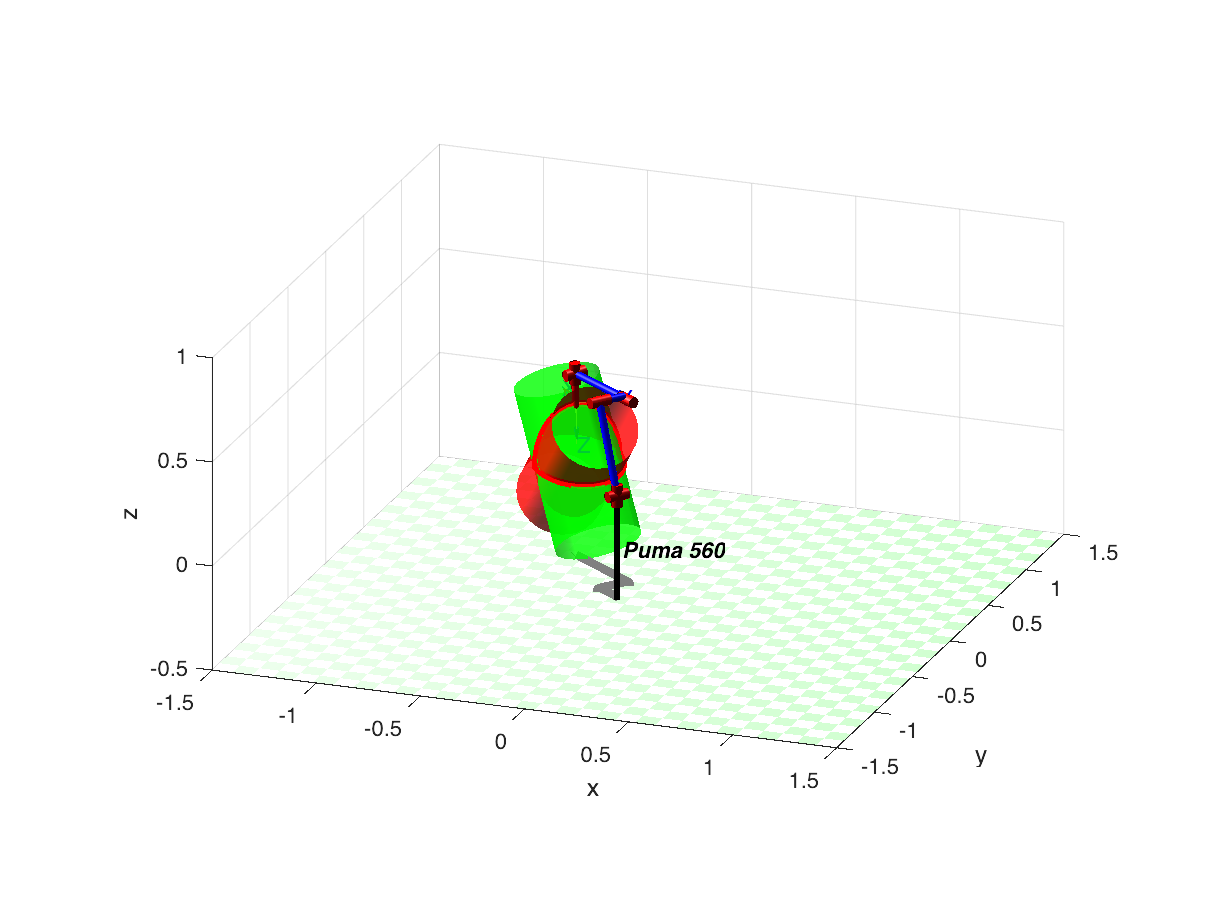

plot3(weld(1,:), weld(2,:), weld(3,:),'r','LineWidth',3);
xyzlabel;
Q= p560.ikine6s(Weld_Pose, 'run');
p560.plot(Q,'view',[20 20], 'zoom',1.5,'workspace', [-1.5 1.5 -1.5 1.5 -0.5 1], 'trail','-','jaxes','zoom',2);

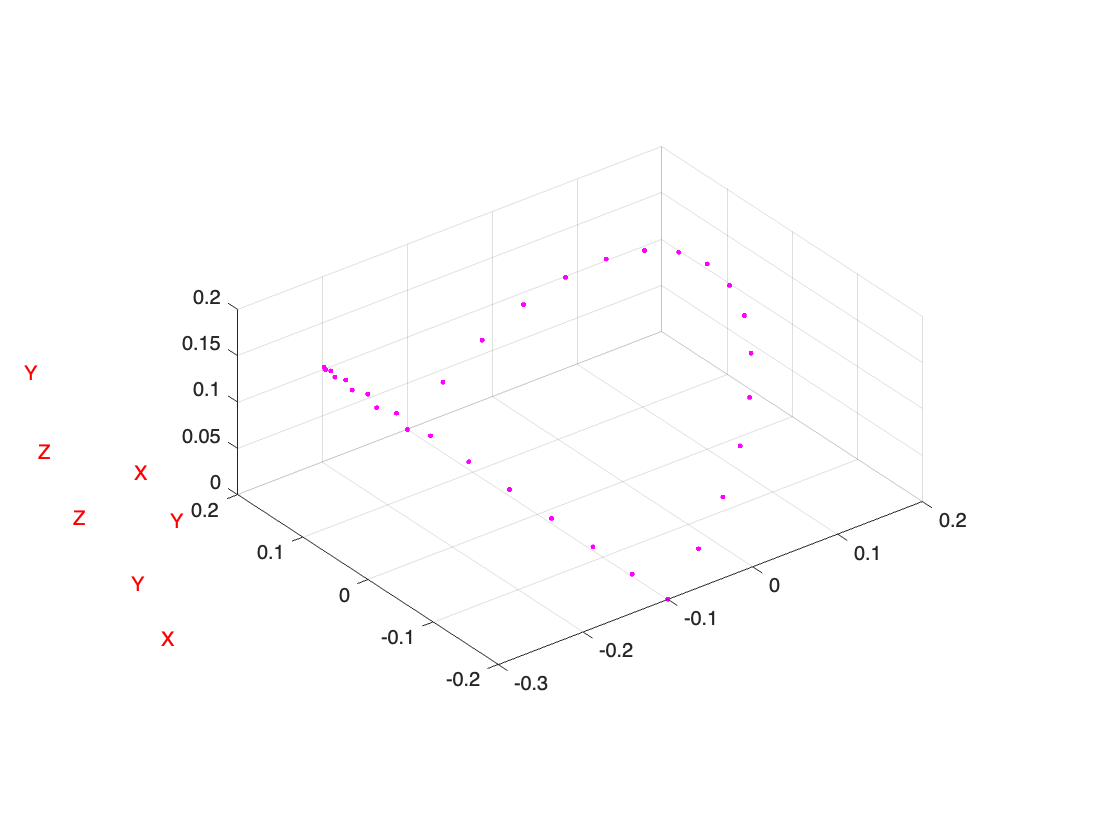

%Draw points
figure
scatter3(cp0(1,:), cp0(2,:), cp0(3,:),'.', 'm', 'LineWidth', 2);
hold on
for i = 1:5:n
    trplot(Weld_Pose(:,:,i), 'length', radius/2, 'arrow', 'width', 0.5, 'color','r')
end

function T_b_a=FVsPlot(F,V,color)
patch('Faces',F,'Vertices',V,'FaceColor',color, ...
         'FaceAlpha',0.8,...
         'EdgeColor',       'none',        ...
         'FaceLighting',    'gouraud',     ...
         'AmbientStrength', 0.15);

% Add a camera light, and tone down the specular highlighting
camlight('headlight');
material('dull');

grid on
xlabel 'X [mm]'
ylabel 'Y [mm]'
zlabel 'Z [mm]'
axis equal
end

## Some help for inspiration

Visit in that order the folder: Hints_Cues

1_Puma_doing_task_example.mlx

2_Puma_doing_task.mp4

3_Drilling_Solution.mlx

4_Puma_doing_drilling_task.avi

5_Puma_doing_welding_task.avi

6_Hint_cue_for welding task.fig